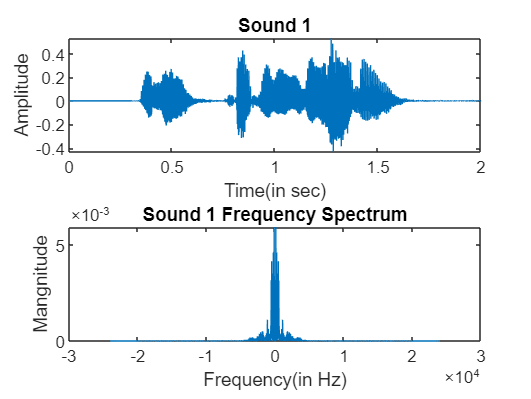

[s1o,Fs1]=audioread('D:\IIITB\semester4\SP\Project\ujjwal.wav');
s1=resample(s1o,48000,44100);
s1f=fftshift(abs(fft(s1))/length(s1));
Fs2=48000;
f=Fs2/2*linspace(-1,1,length(s1f));
t1=linspace(0,2,length(s1));
figure;
subplot(2,1,1);
plot(t1,s1);
title("Sound 1");
xlabel("Time(in sec)");
ylabel("Amplitude");
subplot(2,1,2);
plot(f,s1f);
title("Sound 1 Frequency Spectrum");
xlabel("Frequency(in Hz)");
ylabel("Mangnitude");

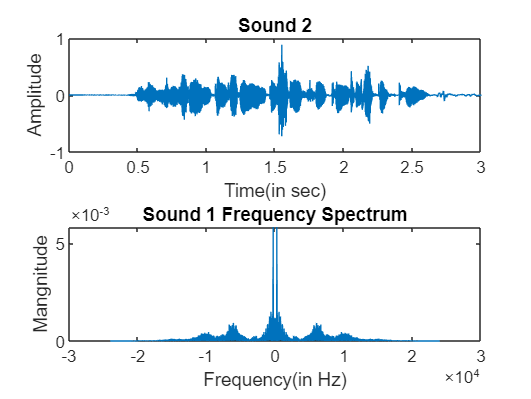

[s2,Fs2]=audioread('D:\IIITB\semester4\SP\Project\shreeya2.wav');
s2f=fftshift(abs(fft(s2))/length(s2));
f2=Fs2/2*linspace(-1,1,length(s2f));
t2=linspace(0,3,length(s2));
figure;
subplot(2,1,1);
plot(t2,s2);
title("Sound 2");
xlabel("Time(in sec)");
ylabel("Amplitude");
subplot(2,1,2);
plot(f2,s2f);
title("Sound 1 Frequency Spectrum");
xlabel("Frequency(in Hz)");
ylabel("Mangnitude");

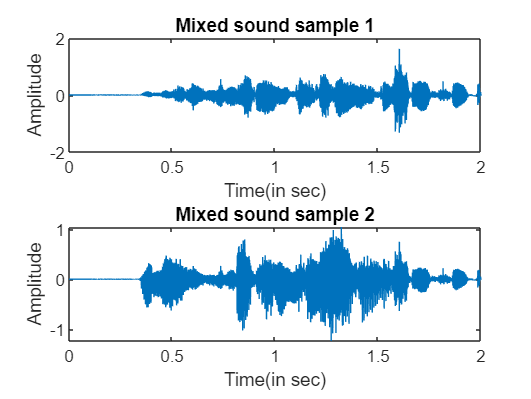


%------------------
% Taking equal lengths of both sounds to mix(least one)
s(:,1)=s1;
s(:,2)=s2(1:length(s1));
rng default;
out=s*randn(2);
figure;
subplot(2,1,1);
plot(t1,out(:,1));
title("Mixed sound sample 1");
xlabel("Time(in sec)");
ylabel("Amplitude");
subplot(2,1,2);
plot(t1,out(:,2));
title("Mixed sound sample 2");
xlabel("Time(in sec)");
ylabel("Amplitude");

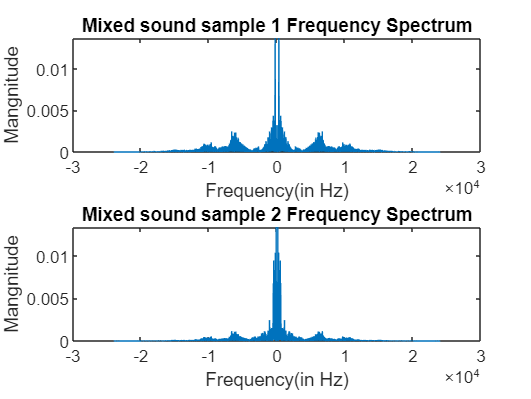


out1f=fftshift(abs(fft(out(:,1)))/length(out(:,1)));
f3=Fs2/2 * linspace(-1,1,length(out1f));
figure;
subplot(2,1,1);
plot(f3,out1f);
title("Mixed sound sample 1 Frequency Spectrum");
xlabel("Frequency(in Hz)");
ylabel("Mangnitude");
out2f=fftshift(abs(fft(out(:,2)))/length(out(:,2)));
f3=Fs2/2 * linspace(-1,1,length(out2f));
subplot(2,1,2);
plot(f3,out2f);
title("Mixed sound sample 2 Frequency Spectrum");
xlabel("Frequency(in Hz)");
ylabel("Mangnitude");


%-----------------------
%Finding correlation between original signals and mixed signal
cr1=corr(s1,out(:,1))

cr1 = 0.2572

cr2=corr(s2(1:length(s1)),out(:,1))

cr2 = 0.9681

%-----------------------

audiowrite('Processed/mixed1.wav',out(:,1),Fs2);

audiowrite('Processed/mixed2.wav',out(:,2),Fs2);

%----------------------------------------
out_w=prewhiten(out);
sep=rica(out_w,2);
separated=transform(sep,out_w);
%-----------------------
%Finding correlation between separated signals and mixed signal
cr1n=corr(separated(:,1),out(:,1))

cr1n = -0.2524

cr2n=corr(separated(:,2),out(:,1))

cr2n = -0.9677

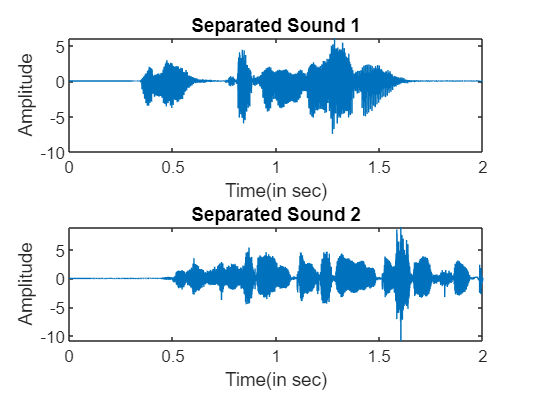

%-----------------------
figure;
subplot(2,1,1);
plot(t1,separated(:,1));
title("Separated Sound 1");
xlabel("Time(in sec)");
ylabel("Amplitude");
subplot(2,1,2);
plot(t1,separated(:,2));
title("Separated Sound 2");
xlabel("Time(in sec)");
ylabel("Amplitude");

audiowrite('Processed/sep1.wav',separated(:,1),Fs2);

audiowrite('Processed/sep2.wav',separated(:,2),Fs2);

function Z = prewhiten(X)
% X = N-by-P matrix for N observations and P predictors
% Z = N-by-P prewhitened matrix

    % 1. Size of X.
    [N,P] = size(X);
    assert(N >= P);

    % 2. SVD of covariance of X. We could also use svd(X) to proceed but N
    % can be large and so we sacrifice some accuracy for speed.
    [U,Sig] = svd(cov(X));
    Sig     = diag(Sig);
    Sig     = Sig(:)';

    % 3. Figure out which values of Sig are non-zero.
    tol = eps(class(X));
    idx = (Sig > max(Sig)*tol);
    assert(~all(idx == 0));

    % 4. Get the non-zero elements of Sig and corresponding columns of U.
    Sig = Sig(idx);
    U   = U(:,idx);

    % 5. Compute prewhitened data.
    mu = mean(X,1);
    Z = bsxfun(@minus,X,mu);
    Z = bsxfun(@times,Z*U,1./sqrt(Sig));
end